## CAUCHY DISTRIBUTION


$$x_{0}=0$$
   


$$\gamma = 1$$


x0 = 0;
gamma = 1;
interval_begin = -10;
interval_end = 10;
number_of_partitions = 100000;

Cauchy Probability Density Function = $\frac{1}{\pi\gamma}\left[\frac{\gamma^{2}}{(x-x_{0})^{2} + \gamma^{2}}\right]$

x = linspace(interval_begin, interval_end, number_of_partitions);
pdf = ((gamma*gamma)./(((x-x0).*(x-x0))+(gamma*gamma)))./(pi*gamma); %cauchy distribution

Now to calculate Cumulative Distribution Fumction,

cdf = zeros(1, number_of_partitions);
for i = 2 : 1 : number_of_partitions
    cdf(1, i) = cdf(1, i-1) + ((interval_end-interval_begin)/number_of_partitions)*pdf(1, i-1);
end

Now plotting CDF and PDF,

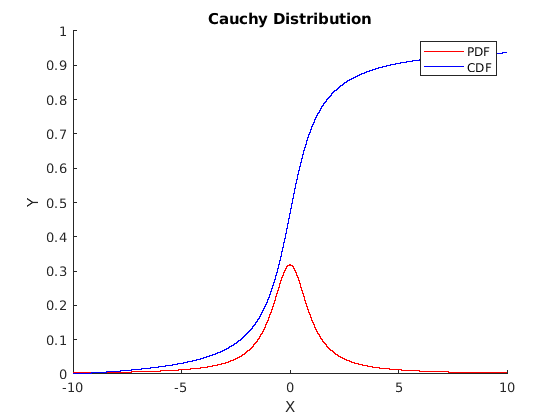

hold on;
plot(x, pdf, 'r');
plot(x, cdf, 'b');
legend(["PDF","CDF"]);
title("Cauchy Distribution");
xlabel("X");
ylabel("Y");
hold off;

Variance of Cauchy Distribution is Undefined